## Resultados Linea Base Sin Obstáculos para largo de paquete 200 Bytes

hold off
%Promedio PDR
%Filas Densidad de menos a mas, columnas Beconing 1,2,5 y 10 Hz

PDR_MEAN(1,:) = [[0.9133887085659589], [0.8161346942586544], [0.8923320018332822], [0.8321552346347071]];
PDR_MEAN(2,:) = [[0.9921012916971417], [0.9868628916815784], [0.9819998862182521], [0.8419093142323053]];
PDR_MEAN(3,:) = [[0.9746073871064256], [0.9453276933265006], [0.8460677029373954], [0.5406153139854364]];
PDR_MEAN(4,:) = [[0.9775314625322509], [0.9346657739605664], [0.7107220327025489], [0.3283954997090765]];

%Promedio CBR:
CBR_MEAN(1,:) = [[0.011403333541813483], [0.020719124392057222], [0.05652193626080831], [0.10433110218835442]];
CBR_MEAN(2,:) = [[0.05297487779267694], [0.10565880740092534], [0.2674288743778989], [0.4847898306818875]];
CBR_MEAN(3,:) = [[0.10034027461820479], [0.19677641328907394], [0.4602267566173964], [0.6904719139974]];
CBR_MEAN(4,:) = [[0.15047644032989593], [0.29233084471711773], [0.6055479395253575], [0.7462343018098923]];

%STD PDR:
PDR_STD(1,:) = [[0.04019233697465388], [0.06815769904958308], [0.1084255521504353], [0.035826661329035746]];
PDR_STD(2,:) = [[0.02627946244374583], [0.01532861825401545], [0.02503873749118952], [0.021606083449467888]];
PDR_STD(3,:) = [[0.008011225998604363], [0.01242736303879581], [0.017901642959185258], [0.009448711862353432]];
PDR_STD(4,:) = [[0.0037385753483510325], [0.012209757283069713], [0.00677824896782002], [0.0022047184213197716]];

%STD CBR:
CBR_STD(1,:) = [[0.0019813332625450886], [0.003913124663890998], [0.01178774338350081], [0.020468790364953873]];
CBR_STD(2,:) = [[0.00583679340248289], [0.007667595088510826], [0.01812455549940223], [0.06847581187937614]];
CBR_STD(3,:) = [[0.0063990043724256275], [0.011871904714828354], [0.026769283990299052], [0.03108594627246089]];
CBR_STD(4,:) = [[0.005074314214127785], [0.009019272111065383], [0.02416813956812075], [0.041852099865289705]];

PDR_T = [0.9538	0.7936	0.6067	0.4554
0.9461	0.7687	0.5730	0.4120
0.9235	0.6965	0.4777	0.2963
0.8864	0.5844	0.3398	0.1548];
PDR_T=PDR_T';

CBR_T = [0.0320	0.1491	0.2982	0.4265
0.0374	0.1683	0.3278	0.4697
0.0534	0.2257	0.4157	0.5947
0.0800	0.3203	0.5543	0.7652];
CBR_T = CBR_T';

NAR_T = [1.0000	0.9998	0.9939	0.9637
1.0000	0.9997	0.9904	0.9449
1.0000	0.9985	0.9711	0.8531
1.0000	0.9917	0.8963	0.6006];
NAR_T = NAR_T';


Sc1 = [ PDR_T(1,:) ; PDR_MEAN(1,:)];
Sc2 = [ PDR_T(2,:) ; PDR_MEAN(2,:)];
Sc3 = [ PDR_T(3,:) ; PDR_MEAN(3,:)];
Sc4 = [ PDR_T(4,:) ; PDR_MEAN(4,:)];

%subplot(2,2,1);

figure (1)
%bar(PDR_MEAN,'DisplayName','PDR_MEAN')
bar(Sc1','DisplayName','PDR_MEAN');
hold on

title('PDR for texitheoretical and simulated');
xlabel('Beacon frequency [Hz]');
ylabel('% PDR');

x=[1 2 3 4];
%x2=[];
%x2(:,1)=x-0.27;
%x2(:,2)=x-0.1;
%x2(:,3)=x+0.1;
%x2(:,4)=x+0.27;
x2 = x + 0.18;
errorbar(x2,PDR_MEAN(1,:),PDR_STD(1,:),'ro');
legend('Theory','Simulation','Location','SouthEast');
ylim([0, 1])
hold off
%subplot(2,2,2);

figure (2)

bar(CBR_MEAN,'DisplayName','CBR_MEAN')
hold on

title('CBR para diferentes densidades y tasa de TX BASELINE');
xlabel('Densidad');
ylabel('% CBR');

x=[1 2 3 4];
x2=[];
x2(:,1)=x-0.27;
x2(:,2)=x-0.1;
x2(:,3)=x+0.1;
x2(:,4)=x+0.27;

errorbar(x2,CBR_MEAN,CBR_STD,'ro');
legend('1Hz','2Hz','5Hz','10Hz','Location','NorthWest');
hold off





## Resultados Linea Base Sin Obstáculos

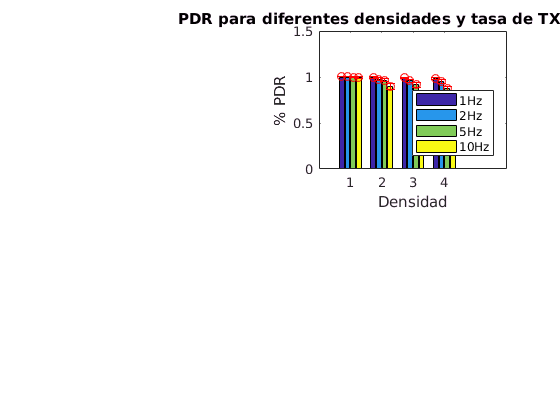


PDR_MEAN(1,:) = [[1.0], [1.0], [0.9978793498954961], [0.9960819860260812]];
PDR_MEAN(2,:) =[[0.9919972937108325], [0.9770449498575693], [0.9627003899853416], [0.8952084656507031]];
PDR_MEAN(3,:) =[[0.9909813836452354], [0.9602173855054569], [0.9154492442579195], [0.8122214435843721]];
PDR_MEAN(4,:) = [[0.9809615853117126], [0.9488063660813131], [0.8744070390530573], [0.6964243859732352]];

PDR_STD(1,:)= [[0.0], [0.0], [0.005083709138579477], [0.008186174612838918]];
PDR_STD(2,:)= [[0.011445590384970353], [0.019337777566239497], [0.01669535628679062], [0.03270312294940898]];
PDR_STD(3,:)= [[0.00769646268354678], [0.0160186700884906], [0.027360798432098658], [0.031829481237557744]];
PDR_STD(4,:)= [[0.010331724747568145], [0.018835080465219676], [0.02737977024790725], [0.027240898978064126]];

CBR_MEAN(1,:) = [[0.0009297885452380953], [0.001861656982070981], [0.006624981090647248], [0.013699089670218975]];
CBR_MEAN(2,:) = [[0.006968018478342114], [0.013591161707736629], [0.03783346091742833], [0.07449354211819087]];
CBR_MEAN(3,:) = [[0.015702499591357527], [0.030852551198371842], [0.0779606294833167], [0.14381982852420971]];
CBR_MEAN(4,:) = [[0.025752390089900424], [0.05130008153431316], [0.11727904289432002], [0.20162834320319173]];

CBR_STD(1,:) = [[0.0003650802035480632], [0.0007352862433331727], [0.0024847755770698557], [0.0049261889854409265]];
CBR_STD(2,:) = [[0.0018214282178001578], [0.003154508817167499], [0.007508520123498131], [0.01462448782273498]];
CBR_STD(3,:) = [[0.002626762256338094], [0.0051524714010566745], [0.013249321092256808], [0.024523119303936438]];
CBR_STD(4,:) = [[0.0037571167657238437], [0.006172884764924531], [0.014852281288074505], [0.027317589647321002]];


figure (1)
bar(PDR_MEAN,'DisplayName','PDR_MEAN')
hold on

title('PDR para diferentes densidades y tasa de TX BASELINE');
xlabel('Densidad');
ylabel('% PDR');

x=[1 2 3 4];
x2=[];
x2(:,1)=x-0.27;
x2(:,2)=x-0.1;
x2(:,3)=x+0.1;
x2(:,4)=x+0.27;

errorbar(x2,PDR_MEAN,PDR_STD,'ro');
legend('1Hz','2Hz','5Hz','10Hz','Location','SouthEast');
hold off

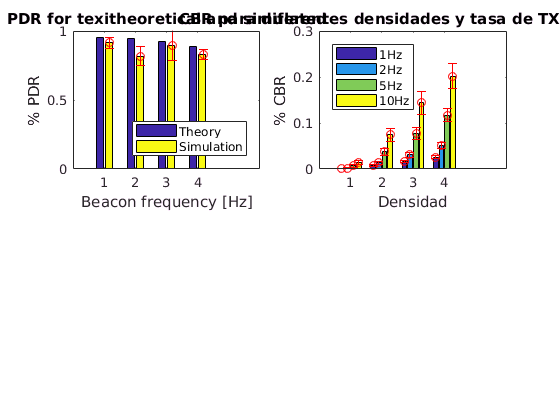

figure (2)

bar(CBR_MEAN,'DisplayName','CBR_MEAN')
hold on

title('CBR para diferentes densidades y tasa de TX BASELINE');
xlabel('Densidad');
ylabel('% CBR');

x=[1 2 3 4];
x2=[];
x2(:,1)=x-0.27;
x2(:,2)=x-0.1;
x2(:,3)=x+0.1;
x2(:,4)=x+0.27;

errorbar(x2,CBR_MEAN,CBR_STD,'ro');
legend('1Hz','2Hz','5Hz','10Hz','Location','NorthWest');
hold off

## Resultados On Street

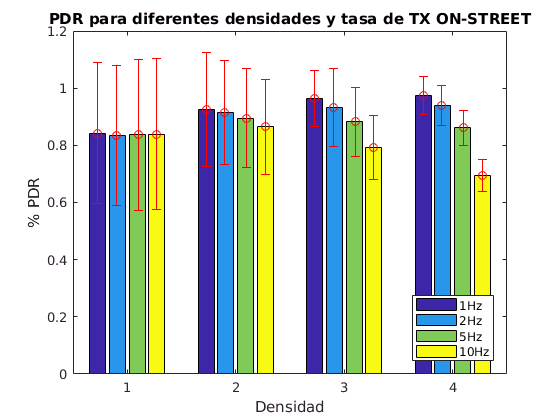

PDR_MEAN_OS(1,:) = [[0.8398351212938393], [0.833027931587082], [0.835279799376015], [0.8390602581460929]];
PDR_MEAN_OS(2,:) = [[0.9249374663694621], [0.9158491112008122], [0.8948623523738173], [0.8659219584316626]];
PDR_MEAN_OS(3,:) = [[0.9643104731439684], [0.9322907552102441], [0.8821901810588139], [0.7917679752557646]];
PDR_MEAN_OS(4,:) = [[0.9735807350442244], [0.9401133618675112], [0.8613031971726539], [0.6935028672800541]];
%Promedio CBR:
CBR_MEAN_OS(1,:) = [[0.0008564801412979579], [0.0020692838354582532], [0.004484571322378717], [0.00839805542547297]];
CBR_MEAN_OS(2,:) = [[0.007257652992766848], [0.01479740560867525], [0.03581770292357496], [0.06894056961407442]];
CBR_MEAN_OS(3,:) = [[0.016180515645476026], [0.032132450604375716], [0.07628323422930944], [0.1429284825917407]];
CBR_MEAN_OS(4,:) = [[0.025820797137148938], [0.05083445022136422], [0.11653672154038018], [0.20144964393506615]];
%STD PDR:
PDR_STD_OS(1,:) = [[0.24847313780495364], [0.24507274110552205], [0.2648412571553357], [0.2650481561268557]];
PDR_STD_OS(2,:) = [[0.19981123289181507], [0.17914893511178573], [0.1730297071183197], [0.16443636860998587]];
PDR_STD_OS(3,:) = [[0.09791410444578248], [0.13413470977437697], [0.12008795737420055], [0.11027788219554681]];
PDR_STD_OS(4,:) = [[0.0674511833889207], [0.06961261853546138], [0.060022199891299505], [0.05561574299952833]];
%STD CBR:
CBR_STD_OS(1,:) =[[0.0003140482638903985], [0.0009237114328346428], [0.0018158992207531256], [0.002750828128052261]];
CBR_STD_OS(2,:) =[[0.0015596247383398583], [0.0036117443115187935], [0.007160372095188621], [0.016940723061039224]];
CBR_STD_OS(3,:) =[[0.0026661411141264166], [0.005962765805301933], [0.012540982185638932], [0.022916030819449158]];
CBR_STD_OS(4,:) =[[0.003238254262216188], [0.00691670261836849], [0.015303043313278695], [0.025888857762253616]];



figure (3)
bar(PDR_MEAN_OS,'DisplayName','PDR_MEAN_OS')
hold on

title('PDR para diferentes densidades y tasa de TX ON-STREET');
xlabel('Densidad');
ylabel('% PDR');

x=[1 2 3 4];
x2=[];
x2(:,1)=x-0.27;
x2(:,2)=x-0.1;
x2(:,3)=x+0.1;
x2(:,4)=x+0.27;

errorbar(x2,PDR_MEAN_OS,PDR_STD_OS,'ro');
legend('1Hz','2Hz','5Hz','10Hz','Location','SouthEast');
hold off

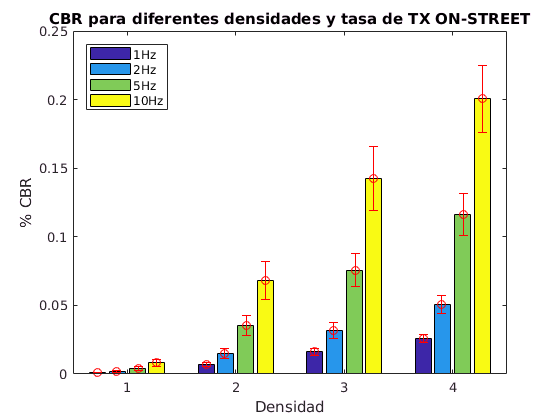

figure (4)

bar(CBR_MEAN_OS,'DisplayName','CBR_MEAN')
hold on

title('CBR para diferentes densidades y tasa de TX ON-STREET');
xlabel('Densidad');
ylabel('% CBR');

x=[1 2 3 4];
x2=[];
x2(:,1)=x-0.27;
x2(:,2)=x-0.1;
x2(:,3)=x+0.1;
x2(:,4)=x+0.27;

errorbar(x2,CBR_MEAN_OS,CBR_STD_OS,'ro');
legend('1Hz','2Hz','5Hz','10Hz','Location','NorthWest');
hold off

## Resultados MovinPed

PDR_MEAN_MP(1,:) = [[0.8398351212938393], [0.833027931587082], [0.835279799376015], [0.8390602581460929]];
PDR_MEAN_MP(2,:) = [[0.9249374663694621], [0.9158491112008122], [0.8948623523738173], [0.8659219584316626]];
PDR_MEAN_MP(3,:) = [[0.9643104731439684], [0.9322907552102441], [0.8821901810588139], [0.7917679752557646]];
PDR_MEAN_MP(4,:) = [[0.9735807350442244], [0.9401133618675112], [0.8613031971726539], [0.6935028672800541]];
%Promedio CBR:
CBR_MEAN_MP(1,:) = [[0.0008564801412979579], [0.0020692838354582532], [0.004484571322378717], [0.00839805542547297]];
CBR_MEAN_MP(2,:) = [[0.007257652992766848], [0.01479740560867525], [0.03581770292357496], [0.06894056961407442]];
CBR_MEAN_MP(3,:) = [[0.016180515645476026], [0.032132450604375716], [0.07628323422930944], [0.1429284825917407]];
CBR_MEAN_MP(4,:) = [[0.025820797137148938], [0.05083445022136422], [0.11653672154038018], [0.20144964393506615]];
%STD PDR:
PDR_STD_MP(1,:) = [[0.24847313780495364], [0.24507274110552205], [0.2648412571553357], [0.2650481561268557]];
PDR_STD_MP(2,:) = [[0.19981123289181507], [0.17914893511178573], [0.1730297071183197], [0.16443636860998587]];
PDR_STD_MP(3,:) = [[0.09791410444578248], [0.13413470977437697], [0.12008795737420055], [0.11027788219554681]];
PDR_STD_MP(4,:) = [[0.0674511833889207], [0.06961261853546138], [0.060022199891299505], [0.05561574299952833]];
%STD CBR:
CBR_STD_MP(1,:) =[[0.0003140482638903985], [0.0009237114328346428], [0.0018158992207531256], [0.002750828128052261]];
CBR_STD_MP(2,:) =[[0.0015596247383398583], [0.0036117443115187935], [0.007160372095188621], [0.016940723061039224]];
CBR_STD_MP(3,:) =[[0.0026661411141264166], [0.005962765805301933], [0.012540982185638932], [0.022916030819449158]];
CBR_STD_MP(4,:) =[[0.003238254262216188], [0.00691670261836849], [0.015303043313278695], [0.025888857762253616]];



figure (5)
bar(PDR_MEAN_MP,'DisplayName','PDR_MEAN_MP')
hold on

title('PDR para diferentes densidades y tasa de TX Movin-Ped');
xlabel('Densidad');
ylabel('% PDR');

x=[1 2 3 4];
x2=[];
x2(:,1)=x-0.27;
x2(:,2)=x-0.1;
x2(:,3)=x+0.1;
x2(:,4)=x+0.27;

errorbar(x2,PDR_MEAN_MP,PDR_STD_MP,'ro');
legend('1Hz','2Hz','5Hz','10Hz','Location','SouthEast');
hold off
figure (4)

bar(CBR_MEAN_MP,'DisplayName','CBR_MEAN')
hold on

title('CBR para diferentes densidades y tasa de TX Movin-Ped');
xlabel('Densidad');
ylabel('% CBR');

x=[1 2 3 4];
x2=[];
x2(:,1)=x-0.27;
x2(:,2)=x-0.1;
x2(:,3)=x+0.1;
x2(:,4)=x+0.27;

errorbar(x2,CBR_MEAN_MP,CBR_STD_MP,'ro');
legend('1Hz','2Hz','5Hz','10Hz','Location','NorthWest');
hold off

## Resultados MultiTX

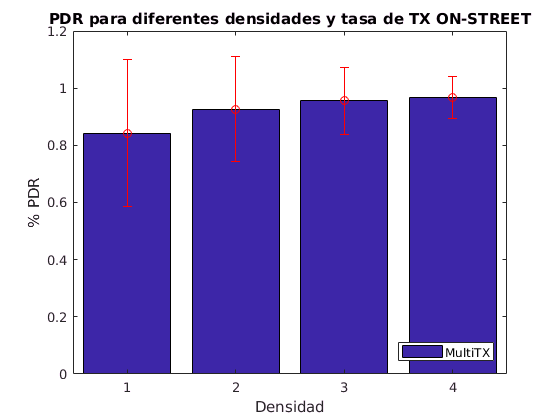

PDR_MEAN_MultiTX(1,:) = [[0.8427834203179689], [], [], []];
PDR_MEAN_MultiTX(2,:) = [[0.9270032971606375], [], [], []];
PDR_MEAN_MultiTX(3,:) = [[0.9568247118024398], [], [], []];
PDR_MEAN_MultiTX(4,:) = [[0.967607024509874], [], [], []];
%Promedio CBR:
CBR_MEAN_MultiTX(1,:) = [[0.0008912284783675102], [], [], []];
CBR_MEAN_MultiTX(2,:) = [[0.006840211870624369], [], [], []];
CBR_MEAN_MultiTX(3,:) = [[0.01642780210428171], [], [], []];
CBR_MEAN_MultiTX(4,:) = [[0.02541306148892013], [], [], []];
%STD PDR:
PDR_STD_MultiTX(1,:) = [[0.25715677594551695], [], [], []];
PDR_STD_MultiTX(2,:) = [[0.18388250312165352], [], [], []];
PDR_STD_MultiTX(3,:) = [[0.11718624478894195], [], [], []];
PDR_STD_MultiTX(4,:) = [[0.07214143227193322], [], [], []];
%STD CBR:
CBR_STD_MultiTX(1,:) = [[0.00031541935910736727], [], [], []];
CBR_STD_MultiTX(2,:) = [[0.0016307204089330942], [], [], []];
CBR_STD_MultiTX(3,:) = [[0.0028392694457956397], [], [], []];
CBR_STD_MultiTX(4,:) = [[0.0032110258097078972], [], [], []];





figure (5)
bar(PDR_MEAN_MultiTX,'DisplayName','PDR_MEAN_OS')
hold on

title('PDR para diferentes densidades y tasa de TX ON-STREET');
xlabel('Densidad');
ylabel('% PDR');

x=[1 2 3 4];
%x2=[];
%x2(:,1)=x-0.27;
%x2(:,2)=x-0.1;
%x2(:,3)=x+0.1;
%x2(:,4)=x+0.27;



errorbar(x,PDR_MEAN_MultiTX(:,1)',PDR_STD_MultiTX(:,1)','ro');
legend('MultiTX','Location','SouthEast');
hold off

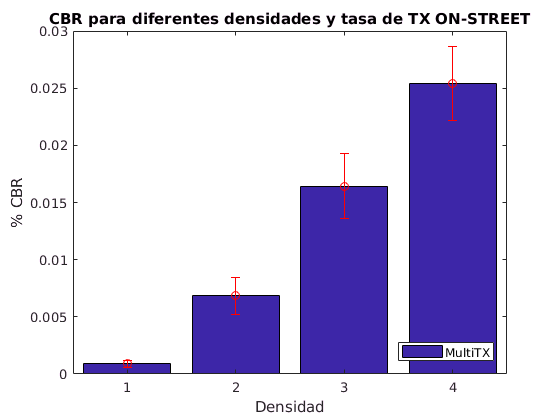



figure (6)

bar(CBR_MEAN_MultiTX,'DisplayName','CBR_MEAN')
hold on

title('CBR para diferentes densidades y tasa de TX ON-STREET');
xlabel('Densidad');
ylabel('% CBR');

x=[1 2 3 4];
x2=[];
x2(:,1)=x-0.27;
x2(:,2)=x-0.1;
x2(:,3)=x+0.1;
x2(:,4)=x+0.27;

errorbar(x,CBR_MEAN_MultiTX,CBR_STD_MultiTX,'ro');
legend('MultiTX','Location','SouthEast');%legend('1Hz','2Hz','5Hz','10Hz','Location','NorthWest');
hold off

## Evaluación Densidad Alta


fig1 = figure (7);

fig1 =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [403 246 560 420]
       Units: 'pixels'

  Show all properties


D = [PDR_MEAN(4,:)' PDR_MEAN_OS(4,:)']';
%size(D)
D3=[D [0 0]'];
D2=[D3 ; [0 0 PDR_MEAN_MultiTX(4,1)] 0 0];


bar(D,'DisplayName','PDR_MEAN')
hold on
x=[1,2,3];  
b1 = bar(x,[0 0 PDR_MEAN_MultiTX(4,1)],'DisplayName','PDR_MEAN')

b1 =   Bar (PDR_MEAN) with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: 'flat'
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3]
        YData: [0 0 0.9676]

  Show all properties


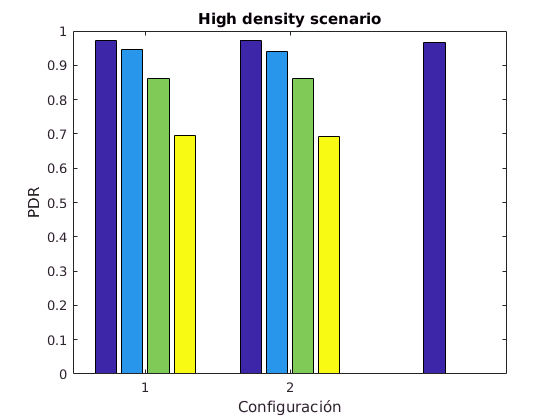

%xticklabels(
b1.BarWidth=0.15;
title('High density scenario');
xlabel('Configuración');
ylabel('PDR');
hold off

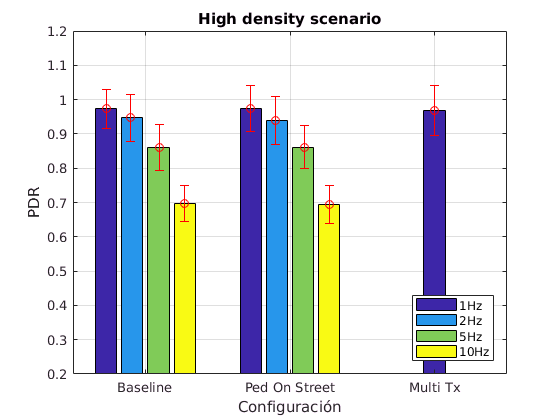

hold on
D_C = [PDR_STD(4,:)' PDR_STD_OS(4,:)']';
x=[1 2];
x2=[];
x2(:,1)=x-0.27;
x2(:,2)=x-0.1;
x2(:,3)=x+0.1;
x2(:,4)=x+0.27;

errorbar(x2,D,D_C,'ro');
x3=[1 2 3];
Y1=[0 0 PDR_MEAN_MultiTX(4,1)];
Y2 =[0 0 PDR_STD_MultiTX(4,1)];
e2=errorbar(x3,Y1,Y2,'ro');
legend('1Hz','2Hz','5Hz','10Hz','Location','SouthEast');
xticks([1 2 3])
xticklabels({'Baseline','Ped On Street','Multi Tx'})
ylim([0.2 1.2]) 
%set(axes,'XTick',['l1' 'll2' 'hhh3']);

grid on

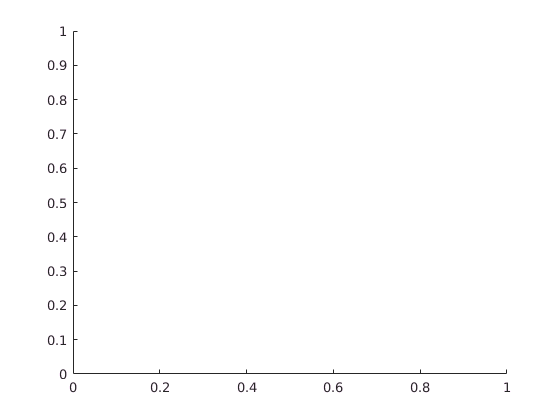

hold off

fig2 = figure (8);
D = [CBR_MEAN(4,:)' CBR_MEAN_OS(4,:)']';
%size(D)
D3=[D [0 0]'];
D2=[D3 ; [0 0 CBR_MEAN_MultiTX(4,1)] 0 0];


bar(D,'DisplayName','PDR_MEAN')
hold on
x=[1,2,3];  
b1 = bar(x,[0 0 CBR_MEAN_MultiTX(4,1)],'DisplayName','PDR_MEAN')

b1 =   Bar (PDR_MEAN) with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: 'flat'
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3]
        YData: [0 0 0.0254]

  Show all properties


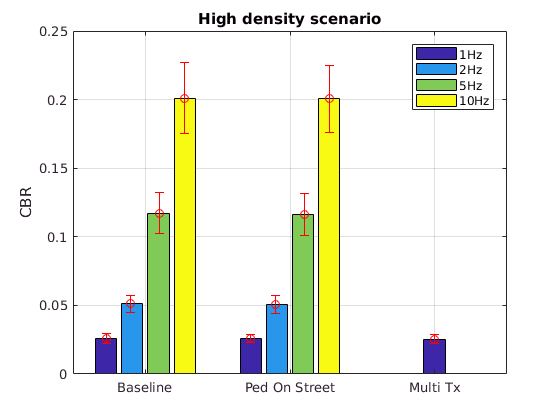

%xticklabels(
b1.BarWidth=0.15;
title('High density scenario');
xlabel('');
ylabel('CBR');
hold on
D_C = [CBR_STD(4,:)' CBR_STD_OS(4,:)']';
x=[1 2];
x2=[];
x2(:,1)=x-0.27;
x2(:,2)=x-0.1;
x2(:,3)=x+0.1;
x2(:,4)=x+0.27;

errorbar(x2,D,D_C,'ro');
x3=[1 2 3];
Y1=[-5 -5 CBR_MEAN_MultiTX(4,1)];
Y2 =[0 0 CBR_STD_MultiTX(4,1)];
e2=errorbar(x3,Y1,Y2,'ro');
legend('1Hz','2Hz','5Hz','10Hz','Location','NorthEast');
xticks([1 2 3])
xticklabels({'Baseline','Ped On Street','Multi Tx'})
ylim([0 0.25]) 
%set(axes,'XTick',['l1' 'll2' 'hhh3']);

grid on



% x=[1 2 3];
% x2=[];
% x2(:,1)=x-0.3;
% x2(:,2)=x-0.2;
% x2(:,3)=x;
% x2(:,3)=x+0.2;
% x2(:,4)=x+0.3;
% 
% 
% errorbar(x,CBR_MEAN_MultiTX,CBR_STD_MultiTX,'ro');
% legend('MultiTX','Location','SouthEast'); %legend('1Hz','2Hz','5Hz','10Hz','Location','NorthWest');
% hold off
